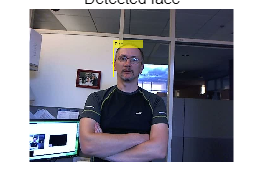

%Step 1: Detect a Face to Track
%Create a cascade detector object
faceDetector=vision.CascadeObjectDetector();
%Read a video frame and run the detector
videoFileReader=VideoReader('visionface.avi');
videoFrame=readFrame(videoFileReader);
bbox=step(faceDetector,videoFrame);
%Draw the returned bounding box around the detected face
videoOut=insertObjectAnnotation(videoFrame,'rectangle',bbox,'Face');
figure,imshow(videoOut),title('Detected face');

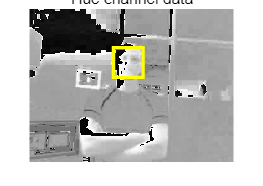


%Step 2:Extract hue data
%Extract hue by converting to the HSV color space
[hueChannel,~,~]=rgb2hsv(videoFrame);
%Display the hue channel data and draw the bounding box around the face.
figure,imshow(hueChannel),title('Hue channel data');
rectangle('Position',bbox(1,:),'LineWidth',2,'EdgeColor',[1 1 0])

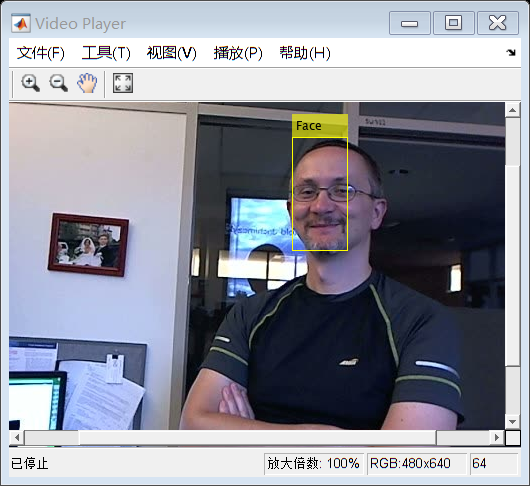


%Step 3 Track the Face

noseDetector = vision.CascadeObjectDetector('Nose','UseROI',true);
noseBBox=step(noseDetector,videoFrame,bbox(1,:));

%create a tracker object
tracker=vision.HistogramBasedTracker;

%Initialize the tracker histogram using the Hue channel pixels from the
%nose
initializeObject(tracker,hueChannel,noseBBox(1,:));

%Create a video player object for displaying video frames
videoPlayer = vision.VideoPlayer;

%Track the face over successive video frames until the video is finished.
while hasFrame(videoFileReader)

    %Extract the next video frame
    videoFrame=readFrame(videoFileReader);

    %RGB -> HSV
    [hueChannel,~,~]=rgb2hsv(videoFrame);

    %Track using the Hue channel data
    bbox=step(tracker,hueChannel);

    %Insert a bounding box around the object being tracked
    videoOut=insertObjectAnnotation(videoFrame,'rectangle',bbox,'Face');

    %Display the annotated video frame using the video player object
    step(videoPlayer,videoOut);
end
release(videoPlayer);



%Step 4 Detect Faces in a Video

%Create a video player object for displaying video frames

函数或变量 'Create' 无法识别。

videoPlayer = vision.VideoPlayer;
while hasFrame(videoFileReader)
    Create a cascade detector object
    faceDetector=vision.CascadeObjectDetector();

    Extract the next video frame
    videoFrame=readFrame(videoFileReader);

    bbox=step(faceDetector,videoFrame);
    Insert a bounding box around the object 
    videoOut=insertObjectAnnotation(videoFrame,'rectangle',bbox,'Face');
    Display the annotated video frame using the video player object
    step(videoPlayer,videoOut);
end
release(videoPlayer);